# Figure S5H, S5I, S5J

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A038_data.mat'],'S','settings','allIF');
conditions = settings.conditions

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

**Gate cells**

xthresh = 2.5e6; %x value of peak
xrange = linspace(0,4.8e6,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end

S5H

conds=[15 10 11 6] ; 
colors = [.5 .5 .5 ;.1 .4 1;  .6 .9 .2;.9 .4 .2];

linetype = {'-','--','-','--'};
timeGate = [0 10];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',2,'linestyle',linetype(i)});
end

ans = 596

ans = 1054

ans = 377

ans = 712

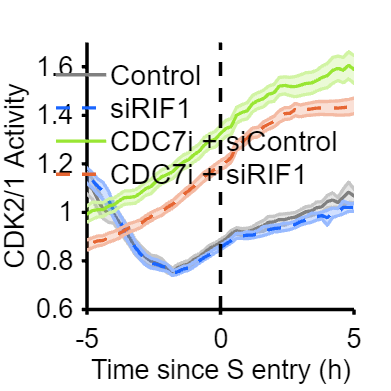


ylabel({'CDK2/1 Activity'});xlabel('Time since S entry (h)');
legend('Control','siRIF1','CDC7i + siControl','CDC7i + siRIF1','box','off','Location','north','fontsize',17);

xlim([-5 5]); 
ylim([.6 1.7]);
vline([0],'k--')

% print_pdf(['fig_S5H.pdf'])



S5I

conds=[15 10 11 6] ; 

colors = [.5 .5 .5; .1 .4 1;  .6 .9 .2;.9 .4 .2];

POI_align = 1;
ally = [];
groups = [];
timeGate = [0 7];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
     
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
         S(conds(i)).apcExpressGate ;

sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 713

ans = 1194

ans = 815

ans = 899

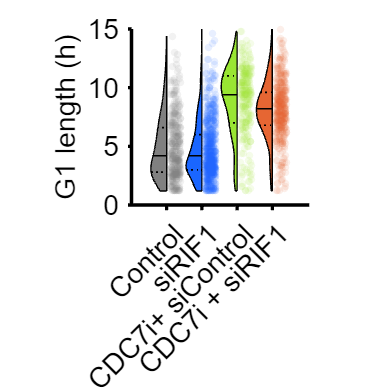


figure('Units', 'Inches', 'Position', [0, 0, 5, 5])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])
yticks(0:5:15)

xticklabels({'Control','siRIF1','CDC7i+ siControl','CDC7i + siRIF1'})
ylim([0 15])
 xtickangle(45)
axis square
set (gca,'linewidth',2,'fontsize',17)


p=mediantest(ally(groups==1),ally(groups==2))

p = 0.4448

p=mediantest(ally(groups==3),ally(groups==4))

p = 1.3254e-07

% print_pdf(['fig_S5I.pdf'])


S5J

colors =  [.5 .5 .5 ;.1 .4 1;  .6 .9 .2;.9 .4 .2];
conds=[15 10 11 6] ;
POI_align = 1;
ally = [];
groups = [];
timeGate = [0 20];

 perc99=[];
    perc=[];
perc1=[];
     for i = 1:length(conds)
       
    
       ind= ~isnan(S(conds(i)).POI(:,1)) & S(conds(i)).POI_time(:,1)>= 3& S(conds(i)).POI_time(:,1)<=5;
      sum(ind)

    
        ydata = [];

         ydata(:, 1) = (((S(conds(i)).iRFP1(ind)-170)));
        ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = (((S(conds(i)).YFP1(ind)-170)));
        ydata(:,4) = (ydata(:,3)./ydata(:,1));
    

           yvals = ydata(:,4);

perc99(i)=prctile(yvals,99);  
perc1(i)=prctile(yvals,1); 

 ind = ydata(:,4) > perc1(i) & ydata(:,4) <perc99(i);

 yvals = ydata(ind,4);

  
              ally = [ally; yvals];
            groups = [groups; repmat(i,size(yvals))];
            length(yvals);

  

      end

ans = 563

ans = 1142

ans = 752

ans = 730

 

cols = repmat({colors(1,:),colors(2,:),colors(3,:),colors(4,:)}',1,1);
groupcol = repmat([colors([1 2 3 4 ],:)],1,1);
 figure ('units','inches','position',[0 0 5 5])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1.5,'histOri','left','widthDiv',[2 1]);

set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'pMCM2(Ser53) / MCM2'])


median_test1 =mediantest(ally(groups==1),ally(groups==2))

median_test1 = 1.3053e-26

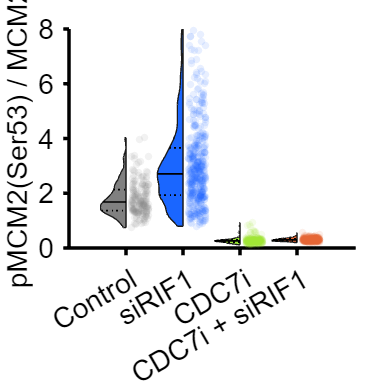




xticklabels({'Control','siRIF1','CDC7i','CDC7i + siRIF1'})
 ylim([0 8])
 set(gca,'linewidth',2,'fontsize',17)

hold off

 % print_pdf(['fig_S5J'])